clearvars -except DDPG_AGENT_2000
rng(13);   % seed 13 — use the same seed for Conventional PID in Chapter 3.6

%% ── 1. Generate 50 test scenarios ───────────────────────────────────────
N = 50;

start_heights  = round(0.5 + 19.5 * rand(N,1), 1);   % [0.5, 20) m
target_heights = round(2.0 + 16.0 * rand(N,1), 1);   % [2,  18) m

T_stop  = 200;
Kp_init = 5;
Ki_init = 2.5;
Kd_init = 1;

%% ── 2. Pre-allocate storage ──────────────────────────────────────────────
RiseTime    = nan(N,1);
SettlingTime= nan(N,1);
Overshoot   = nan(N,1);
SS_Error    = nan(N,1);
ISE         = nan(N,1);

t_all = cell(N,1);
h_all = cell(N,1);

fprintf('\n%-6s %-10s %-10s  %-10s %-12s %-12s %-10s %-10s\n', ...
    'Scen','Start(m)','Target(m)','Rise(s)','Settling(s)','Overshoot(%)','SSE(m)','ISE');

Scen   Start(m)   Target(m)   Rise(s)    Settling(s)  Overshoot(%) SSE(m)     ISE       


fprintf('%s\n', repmat('-',1,85));

-------------------------------------------------------------------------------------



%% ── 3. Simulation loop ───────────────────────────────────────────────────
for i = 1:N
    sh = start_heights(i);
    th = target_heights(i);

    try
        inDDPG = Simulink.SimulationInput('Water_Tank');
        inDDPG = setVariable(inDDPG, 'target_h',              th);
        inDDPG = setVariable(inDDPG, 'start_h',               sh);
        inDDPG = setVariable(inDDPG, 'Kp_init',               Kp_init);
        inDDPG = setVariable(inDDPG, 'Ki_init',               Ki_init);
        inDDPG = setVariable(inDDPG, 'Kd_init',               Kd_init);
        inDDPG = setVariable(inDDPG, 'epCount',               9999);
        inDDPG = setVariable(inDDPG, 'DDPG_AGENT_2000', DDPG_AGENT_2000);
        inDDPG = inDDPG.setModelParameter('StopTime', num2str(T_stop));
        out    = sim(inDDPG);

        t = out.tout(:);
        h = out.logsout.get('Height').Values.Data(:);

        info = stepinfo(h, t, th, sh, ...
            'SettlingTimeThreshold', 0.05, ...
            'RiseTimeLimits', [0.1 0.9]);

        RiseTime(i)     = info.RiseTime;
        SettlingTime(i) = info.SettlingTime;
        Overshoot(i)    = info.Overshoot;
        ISE(i)          = trapz(t, (h - th).^2);
        SS_Error(i)     = abs(mean(h(t >= t(end)-10)) - th);

        t_all{i} = t;
        h_all{i} = h;

    catch ME
        warning('Scenario %d failed: %s', i, ME.message);
    end

    fprintf('%-6d %-10.1f %-10.1f  %-10.2f %-12.2f %-12.2f %-10.4f %-10.2f\n', ...
        i, sh, th, RiseTime(i), SettlingTime(i), Overshoot(i), SS_Error(i), ISE(i));
end

1      15.7       13.0        5.71       10.35        10.50        0.0004     17.25     
2      5.1        10.8        1.23       6.16         30.01        0.0000     25.06     
3      16.6       4.2         31.74      37.58        1.06         0.0000     1756.09   
4      19.3       3.6         38.74      45.98        1.06         0.0000     3353.43   
5      19.5       5.9         31.29      37.01        1.31         0.0000     2116.11   
6      9.3        4.4         15.14      17.89        4.01         0.0009     139.29    
7      12.4       16.8        1.33       1.75         3.67         0.0009     8.95      
8      15.6       12.9        5.73       10.37        10.66        0.0002     17.30     
9      13.0       5.8         19.02      22.47        3.23         0.1265     378.46    
10     14.6       11.1        7.82       11.11        5.11         0.0156     38.92     
11     1.2        10.9        2.07       6.06         15.87        0.0005     89.05     
12     6.3        3.2


%% ── 4. Per-scenario results table ───────────────────────────────────────
T_results = table((1:N)', start_heights, target_heights, ...
    abs(target_heights - start_heights), ...
    round(RiseTime,2), round(SettlingTime,2), ...
    round(Overshoot,2), round(SS_Error,4), round(ISE,2), ...
    'VariableNames', {'Scenario','Start_m','Target_m','StepSize_m', ...
    'RiseTime_s','SettlingTime_s','Overshoot_pct','SSError_m','ISE'});

disp('=== DDPG-PID PER-SCENARIO RESULTS ===');

=== DDPG-PID PER-SCENARIO RESULTS ===


disp(T_results);

    Scenario    Start_m    Target_m    StepSize_m    RiseTime_s    SettlingTime_s    Overshoot_pct    SSError_m     ISE  
    ________    _______    ________    __________    __________    ______________    _____________    _________    ______

        1        15.7          13          2.7          5.71           10.35              10.5         0.0004       17.25
        2         5.1        10.8          5.7          1.23            6.16             30.01              0       25.06
        3        16.6         4.2         12.4         31.74           37.58              1.06              0      1756.1
        4        19.3         3.6         15.7         38.74           45.98       

writetable(T_results, 'ddpg_results.csv');
fprintf('Saved: ddpg_results.csv\n');

Saved: ddpg_results.csv



%% ── 5. Summary statistics ────────────────────────────────────────────────
metrics_data   = {RiseTime, SettlingTime, Overshoot, SS_Error, ISE};
metrics_labels = {'Rise Time (s)','Settling Time (s)','Overshoot (%)','SS Error (m)','ISE'};
nM = numel(metrics_data);

Metric   = metrics_labels';
Mean_val = cellfun(@(x) mean(x(~isnan(x))),   metrics_data)';
Std_val  = cellfun(@(x) std(x(~isnan(x))),    metrics_data)';
Median_v = cellfun(@(x) median(x(~isnan(x))), metrics_data)';
Min_val  = cellfun(@(x) min(x(~isnan(x))),    metrics_data)';
Max_val  = cellfun(@(x) max(x(~isnan(x))),    metrics_data)';
IQR_val  = cellfun(@(x) iqr(x(~isnan(x))),    metrics_data)';

T_summary = table(Metric, Mean_val, Std_val, Median_v, Min_val, Max_val, IQR_val, ...
    'VariableNames',{'Metric','Mean','Std','Median','Min','Max','IQR'});

fprintf('\n=== DDPG-PID SUMMARY STATISTICS (N=50) ===\n');


=== DDPG-PID SUMMARY STATISTICS (N=50) ===


disp(T_summary);

           Metric              Mean        Std         Median        Min        Max         IQR   
    _____________________    ________    ________    __________    _______    _______    _________

    {'Rise Time (s)'    }      10.675      11.253        5.7164    0.27622      38.74       17.185
    {'Settling Time (s)'}      14.932      11.844        10.549     1.7532     45.983       16.419
    {'Overshoot (%)'    }      13.021      28.644         5.032    0.86815     189.62       7.5881
    {'SS Error (m)'     }    0.016721    0.039818    7.4238e-05          0    0.15333    0.0029834
    {'ISE'              }      425.45      780.14         64.25     0.1712     3353.4        452.6



writetable(T_summary, 'ddpg_summary.csv');
fprintf('Saved: ddpg_summary.csv\n');

Saved: ddpg_summary.csv


Saved: Fig1a_DDPG_StepResponses_p1of3.png


Saved: Fig1b_DDPG_StepResponses_p2of3.png


Saved: Fig1c_DDPG_StepResponses_p3of3.png



%% ── 6. FIGURES 1a, 1b, 1c: 10 representative step responses across 3 pages
%   Page 1 (2x2): scenarios 1-4
%   Page 2 (2x2): scenarios 5-8
%   Page 3 (1x2): scenarios 9-10
sel   = round(linspace(1, N, 10));
blue  = [0 0.447 0.741];

% Helper inline plotting routine via local function (see bottom of script).
% We split the 10 selected scenarios into three groups.
groups       = {sel(1:4), sel(5:8), sel(9:10)};
layouts      = {[2 2],    [2 2],    [1 2]};
fig_names    = {'Fig1a_DDPG_StepResponses_p1of3.png', ...
                'Fig1b_DDPG_StepResponses_p2of3.png', ...
                'Fig1c_DDPG_StepResponses_p3of3.png'};
fig_titles   = {'DDPG-PID Step Responses — Page 1 of 3 (Scenarios 1–4 of 10)', ...
                'DDPG-PID Step Responses — Page 2 of 3 (Scenarios 5–8 of 10)', ...
                'DDPG-PID Step Responses — Page 3 of 3 (Scenarios 9–10 of 10)'};
fig_positions = {[50 50 1000 900], [50 50 1000 900], [50 50 1000 480]};

for g = 1:numel(groups)
    idx_group = groups{g};
    rows = layouts{g}(1);
    cols = layouts{g}(2);

    figH = figure('Name', fig_titles{g}, 'Color','w', 'Position', fig_positions{g});
    tiledlayout(rows, cols, 'TileSpacing','compact', 'Padding','compact');

    for kk = 1:numel(idx_group)
        i = idx_group(kk);
        nexttile;
        if ~isempty(t_all{i})
            plot(t_all{i}, h_all{i}, 'Color', blue, 'LineWidth', 1.8);
            hold on;
            yline(target_heights(i),        'k--', 'LineWidth', 1.2, 'HandleVisibility','off');
            yline(target_heights(i) * 1.05, 'k:',  'LineWidth', 0.8, 'HandleVisibility','off');
            yline(target_heights(i) * 0.95, 'k:',  'LineWidth', 0.8, 'HandleVisibility','off');
            hold off;
            % Annotate metrics on plot
            txt = sprintf('RT: %.1fs\nST: %.1fs\nOS: %.1f%%', ...
                RiseTime(i), SettlingTime(i), Overshoot(i));
            text(5, target_heights(i)*0.25, txt, 'FontSize',9, 'Color','k');
        end
        title(sprintf('S%d: %.1f to %.1f m', i, start_heights(i), target_heights(i)), ...
            'FontSize',11);
        xlabel('Time (s)','FontSize',10);
        ylabel('Height (m)','FontSize',10);
        ylim([0 20]); grid on; box on;
    end
    sgtitle(fig_titles{g}, 'FontSize',12,'FontWeight','bold');
    exportgraphics(figH, fig_names{g}, 'Resolution',300);
    fprintf('Saved: %s\n', fig_names{g});
end

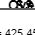


%% ── 7. FIGURE 2: Per-scenario metric bar plots ───────────────────────────
% Shows how each metric varies across all 50 scenarios sorted by step size
[step_sorted, sort_idx] = sort(abs(target_heights - start_heights));

fig2 = figure('Name','DDPG Per-Scenario Metrics','Color','w','Position',[50 50 1300 900]);
tiledlayout(3,2,'TileSpacing','compact','Padding','compact');

plot_data  = {RiseTime, SettlingTime, Overshoot, SS_Error, ISE};
plot_ylbls = {'Rise Time (s)','Settling Time (s)','Overshoot (%)','SS Error (m)','ISE'};

for m = 1:nM
    nexttile;
    bar(1:N, plot_data{m}(sort_idx), 'FaceColor', blue, 'EdgeColor','none', 'FaceAlpha',0.8);
    hold on;
    yline(mean(plot_data{m}(~isnan(plot_data{m}))), 'r--', 'LineWidth', 1.5, ...
        'DisplayName', sprintf('Mean = %.2f', mean(plot_data{m}(~isnan(plot_data{m})))));
    hold off;
    xlabel('Scenarios (sorted by step size)','FontSize',8);
    ylabel(plot_ylbls{m},'FontSize',9);
    title(plot_ylbls{m},'FontSize',9,'FontWeight','bold');
    legend('Location','northeast','FontSize',7);
    grid on; box on;
    xlim([0 N+1]);
end

% 6th tile: step size reference
nexttile;
bar(1:N, step_sorted, 'FaceColor',[0.6 0.6 0.6],'EdgeColor','none','FaceAlpha',0.8);
xlabel('Scenarios (sorted by step size)','FontSize',8);
ylabel('Step Size (m)','FontSize',9);
title('Step Size Reference','FontSize',9,'FontWeight','bold');
grid on; box on; xlim([0 N+1]);

sgtitle('DDPG-PID Per-Scenario Performance Metrics (Sorted by Step Size, N=50)', ...
    'FontSize',11,'FontWeight','bold');
exportgraphics(fig2,'Fig2_DDPG_Metrics.png','Resolution',300);

fprintf('Saved: Fig2_DDPG_Metrics.png\n');

Saved: Fig2_DDPG_Metrics.png



%% ── 8. FIGURE 3: Box plots ───────────────────────────────────────────────
fig3 = figure('Name','DDPG Box Plots','Color','w','Position',[50 50 1300 500]);
tiledlayout(1,5,'TileSpacing','compact','Padding','compact');

for m = 1:nM
    nexttile;
    data_clean = plot_data{m}(~isnan(plot_data{m}));
    bp = boxplot(plot_data{m}, 'Width',0.5,'Symbol','o','Colors', blue);
    set(bp,'LineWidth',1.5);
    h_box = findobj(gca,'Tag','Box');
    patch(get(h_box,'XData'), get(h_box,'YData'), blue, 'FaceAlpha',0.35);
    hold on;
    % Overlay individual data points (jittered)
    jitter = 0.08 * randn(N,1);
    scatter(ones(N,1) + jitter, plot_data{m}, 20, 'k', 'filled', ...
        'MarkerFaceAlpha',0.3, 'HandleVisibility','off');
    hold off;
    title(plot_ylbls{m},'FontSize',9,'FontWeight','bold');
    set(gca,'XTick',[]);
    ylabel(plot_ylbls{m},'FontSize',8);
    grid on; box on;
    % Print mean and std below title
    xlabel(sprintf('Mean=%.2f\nSD=%.2f', mean(data_clean), std(data_clean)), ...
        'FontSize',7);
end

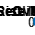

sgtitle('DDPG-PID Performance Distribution Across 50 Test Scenarios', ...
    'FontSize',11,'FontWeight','bold');
exportgraphics(fig3,'Fig3_DDPG_Boxplot.png','Resolution',300);

fprintf('Saved: Fig3_DDPG_Boxplot.png\n');

Saved: Fig3_DDPG_Boxplot.png




%% ── 9. FIGURE 4: Settling Time, ISE and Overshoot vs step size ──────────

step_sizes = abs(target_heights - start_heights);

fig4 = figure('Name','DDPG Performance vs Step Size','Color','w','Position',[50 50 1600 480]);
tiledlayout(1,3,'TileSpacing','compact','Padding','compact');

pairs     = {SettlingTime, ISE, Overshoot};
pair_lbls = {'Settling Time (s)', 'ISE', 'Overshoot (%)'};

for m = 1:3
    nexttile;
    valid = ~isnan(pairs{m});
    scatter(step_sizes(valid), pairs{m}(valid), 55, blue, 'filled', ...
        'MarkerEdgeColor','w','LineWidth',0.5);
    hold on;
    % Trend line
    p_fit = polyfit(step_sizes(valid), pairs{m}(valid), 1);
    xs = linspace(min(step_sizes), max(step_sizes), 100);
    plot(xs, polyval(p_fit, xs), 'r--', 'LineWidth', 1.8, ...
        'DisplayName', sprintf('Trend (slope=%.2f)', p_fit(1)));
    hold off;
    xlabel('Step Size |Target - Start| (m)','FontSize',10);
    ylabel(pair_lbls{m},'FontSize',10);
    title(sprintf('%s vs. Step Size', pair_lbls{m}),'FontSize',10,'FontWeight','bold');
    legend('Location','northwest','FontSize',8);
    % Correlation coefficient
    r = corrcoef(step_sizes(valid), pairs{m}(valid));
    text(min(step_sizes)+0.5, max(pairs{m}(valid))*0.92, ...
        sprintf('r = %.3f', r(1,2)), 'FontSize',9,'Color','r');
    grid on; box on;
end
sgtitle('DDPG-PID Performance vs. Step Size (N=50)','FontSize',11,'FontWeight','bold');
exportgraphics(fig4,'Fig4_DDPG_Performance_vs_StepSize.png','Resolution',300);

fprintf('Saved: Fig4_DDPG_Performance_vs_StepSize.png\n');

Saved: Fig4_DDPG_Performance_vs_StepSize.png


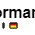


%% ── 10. FIGURE 5: Normalised performance across scenarios (heat strip) ───
% Shows all 5 metrics normalised 0-1 per metric, sorted by step size
% Useful for spotting which scenarios were hard for the agent

norm_mat = nan(nM, N);
for m = 1:nM
    d = plot_data{m};
    mn = min(d(~isnan(d)));
    mx = max(d(~isnan(d)));
    norm_mat(m,:) = (d - mn) / (mx - mn);
end

fig5 = figure('Name','DDPG Performance Heatstrip','Color','w','Position',[50 50 1300 380]);
imagesc(norm_mat(:, sort_idx));
colormap(flipud(hot));
clim([0 1]);
cb5 = colorbar;
cb5.Label.String = 'Normalised metric value (0=best, 1=worst)';
set(gca,'YTick',1:nM,'YTickLabel',plot_ylbls,'FontSize',9);
xlabel('Scenarios sorted by step size (small to large)','FontSize',10);
title('DDPG-PID Normalised Performance Across 50 Scenarios', ...
    'FontSize',10,'FontWeight','bold');
exportgraphics(fig5,'Fig5_DDPG_Heatstrip.png','Resolution',300);

fprintf('Saved: Fig5_DDPG_Heatstrip.png\n');

Saved: Fig5_DDPG_Heatstrip.png



fprintf('\nAll done. Files saved to: %s\n', pwd);


All done. Files saved to: C:\Users\HP\Desktop\BELLS\FINAL YEAR PROJECT\PROJECT MATLAB\CURRENT WORK
